# Planar Surface Drag Verification

verify the functions for planar surface drag I am using are consistent with the results from Fleeman

clear; close; clc;

## Initialize Variables

M = 2; % Mach number (~)
n_surface = 2; % number of planar surfaces
h = convlength(20E3, "ft", "m"); % altitude (m)
c_mac = convlength(1.108, "ft", "m"); % mean aerodynamic cord (m)
S_ref = 50.26 * convlength(1, "in", "m")^2; % refrence area (m^2)
S_surface = 367 * convlength(1, "in", "m")^2; % wetted area of the surface (m^2)
delta_LE = deg2rad(10.01); % Leading edge section angle (radians)
Lambda_LE = deg2rad(45); % Leading edge sweep angle (radians)
t_mac = convlength(.585, "in", "m"); % maximum thickness of mean aerodynamic cord (m)
b = convlength(32.2, "in", "m"); % span (m)

% Computate simple parameters 
[~,a,~,rho] = atmosisa(h); % speed of sound (m/s) and atmospheric density (kg/m^3) from altitude and isa statndard atmosphere
V = M.*a; % speed (m/s) from mach number and speed of sound
q = .5 * rho .* V.^2; % dynamic pressure (Pa)

% compute friction drag component (expect value is .090)
C_D_0_surface_friction = dragCoeff_friction_surface(M, q, c_mac, S_surface, S_ref, n_surface) % Coefficient of drag due to surface friction (~)

C_D_0_surface_friction = 0.0899


% compute wave drag component (expect value is .024)
C_D_0_surface_wave = dragCoeff_wave_surface(M, n_surface, delta_LE, Lambda_LE, t_mac, b, S_ref) % Coefficient of drag due to shockwaves (~)

C_D_0_surface_wave =     0.7950    0.0930    0.0240    0.0060


## Repoduce Fleeman Graph

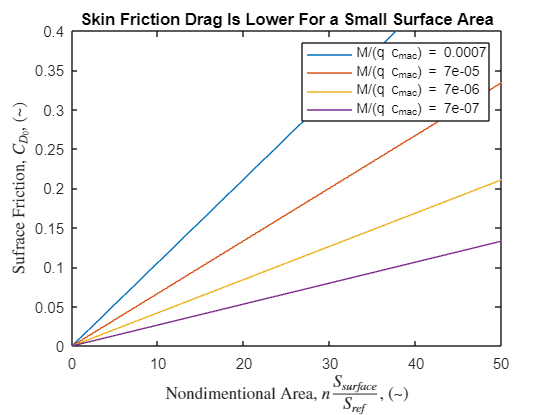

for spdParam = [1E-2, 1E-3, 1E-4, 1E-5] * convlength(1,"ft","m") / convforce(1,"lbf","N") % M/q*c_mac (m/N)
    % define c_mac to achive desired speed parameter M/(q*c_mac)
    c_mac = M/(q*spdParam); % mean aerodynamic cord (m)
    
    % Create a domain of Surface areas to plot
    S_surface = linspace(0, 50*S_ref/n_surface, 100); % wetted area of the surface (m^2)
    
    % compute drag component (expect value is .090)
    C_D_0_surface_friction = dragCoeff_friction_surface(M, q, c_mac, S_surface, S_ref, n_surface); % Coefficient of drag due to surface friction (~)
    
    % compute nondimentional area
    S_nd = n_surface*S_surface/S_ref;
    
    % plot drag
    plot(S_nd, C_D_0_surface_friction, "DisplayName",sprintf("M/(q c_{mac}) = %.1g", spdParam));
    hold on;
    title("Skin Friction Drag Is Lower For a Small Surface Area"); xlabel("Nondimentional Area, $n \frac{S_{surface}}{S_{ref}}$, (~)","Interpreter","latex"); ylabel("Sufrace Friction, $C_{D_0}$, (~)", "Interpreter","latex");
    xlim([0,50]); ylim([0,.4]);
    legend;
end


% wave drag and total drag confirm in plot_C_D_0_surface_vs_mach.mlx

nPoints = 1000

Unable to perform assignment because the size of the left side is 4-by-1 and the size of the right side is 1-by-100.